# Analyzing the data for lidar and wind field (seed 1801)

## 1. Lidar data

Importing the data:

directory = 'D:\Cursos\UCB - Wind Energy Basics\LidarAssistedControl-SummerGames2025\Hurdles\solis_lidar_data';
file_name = ['URef_18_Seed_1801_lidar_data_4BeamPulsed','.csv'];
data_lidar = readtable(fullfile(directory,file_name))

data_lidar = 2640×22 table
    time    beamID    lineOfSightWindSpeed1    lineOfSightWindSpeed2    lineOfSightWindSpeed3    lineOfSightWindSpeed4    lineOfSightWindSpeed5    lineOfSightWindSpeed6    lineOfSightWindSpeed7    lineOfSightWindSpeed8    lineOfSightWindSpeed9    lineOfSightWindSpeed10    isValid1    isValid2    isValid3    isValid4    isValid5    isValid6    isValid7    isValid8    isValid9    isValid10
    ____    ______    _____________________    _____________________    _____________________    __________________

All the columns `isValid` are the same:

isequal(data_lidar.isValid1,data_lidar.isValid2,data_lidar.isValid3,data_lidar.isValid4,data_lidar.isValid5,data_lidar.isValid6,data_lidar.isValid7,data_lidar.isValid8,data_lidar.isValid9,data_lidar.isValid10)

ans = logical
   1

So only `isValid1` will be used for chosing the non-zero values:

idx_nonzero = logical(data_lidar.isValid1);

The mean values for the selected $v_{\textrm{LOS}}$ are:

v_LOS_selected = 1:10;
mean(data_lidar(idx_nonzero,v_LOS_selected+2))

ans = 1×10 table
    lineOfSightWindSpeed1    lineOfSightWindSpeed2    lineOfSightWindSpeed3    lineOfSightWindSpeed4    lineOfSightWindSpeed5    lineOfSightWindSpeed6    lineOfSightWindSpeed7    lineOfSightWindSpeed8    lineOfSightWindSpeed9    lineOfSightWindSpeed10
    _____________________    _____________________    _____________________    _____________________    _____________________    _____________________    _____________________    _____________________    _____________________    ______________________
            17.44                    17.45                   17.436                   17.432                   17.421                   17.

Plot for the selected $v_{\textrm{LOS}}$:

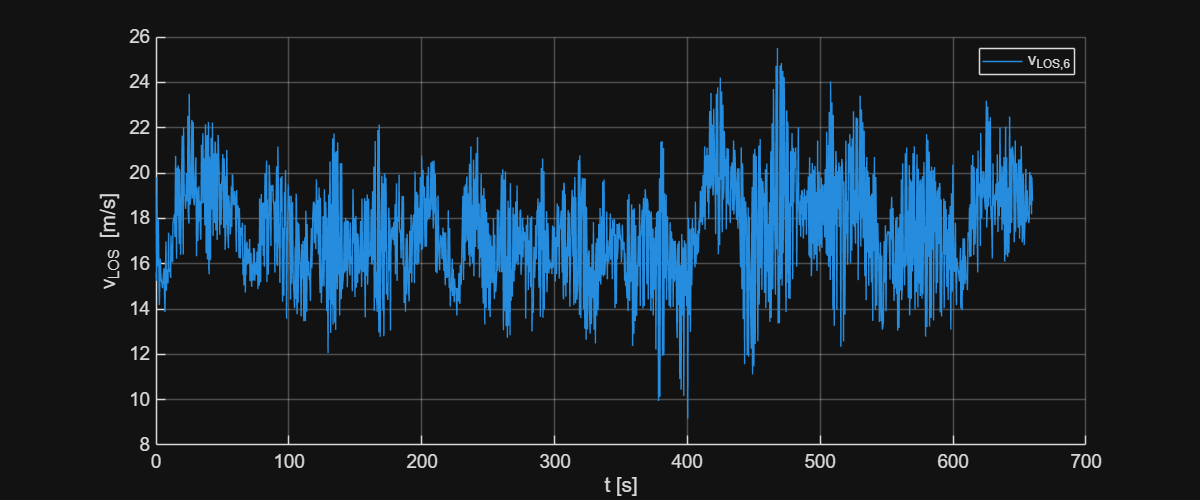

v_LOS_selected = 6;

f = figure;
f.Position([3 4]) = [1200 500];

hold on
for v_LOS = v_LOS_selected
    plot(data_lidar.time(idx_nonzero),data_lidar.(v_LOS+2)(idx_nonzero))
end
hold off
legend("v_{LOS,"+string(v_LOS_selected)+"}")
xlabel('t [s]'); ylabel("v_{LOS} [m/s]")

ax = gca;
ax.FontSize = 14;
grid on

## 2. Wind field data

Importing the data:

directory = 'D:\Cursos\UCB - Wind Energy Basics\LidarAssistedControl-SummerGames2025\Hurdles\TurbulentWind';
file_name = ['URef_18_Seed_1801','.csv'];
data_wind = readtable(fullfile(directory,file_name))

data_wind = 2400×2 table
    time     REWS 
    ____    ______
       0    17.844
    0.25    17.824
     0.5    17.815
    0.75     17.79
       1    17.723
    1.25    17.721
     1.5    17.657
    1.75    17.629
       2    17.552
    2.25     17.46
     2.5    17.471
    2.75    17.557
       3     17.55
    3.25    17.526
     3.5    17.508
    3.75    17.505

mean(data_wind.REWS)

ans = 17.7270

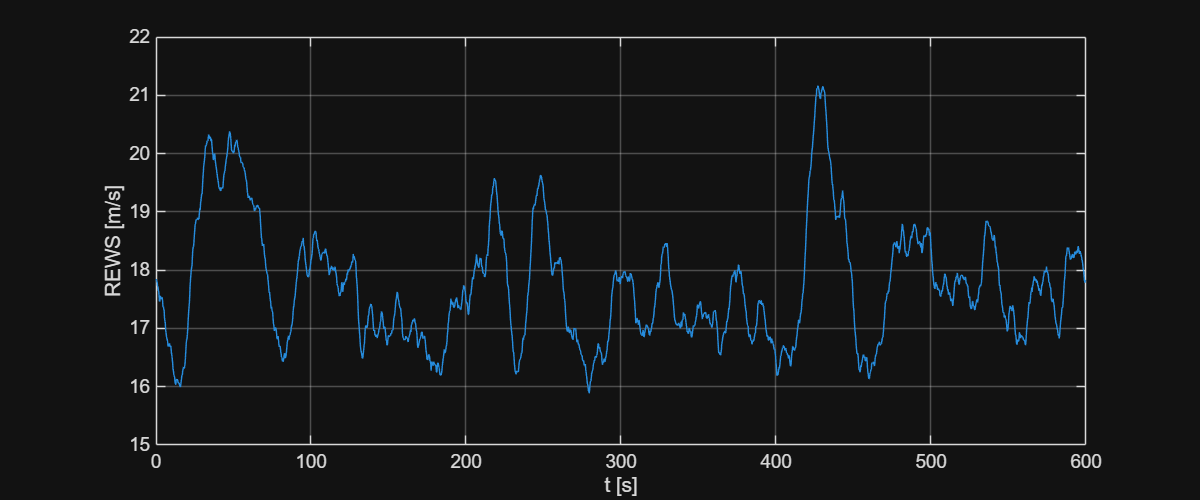

f = figure;
f.Position([3 4]) = [1200 500];

plot(data_wind.time,data_wind.REWS)
xlabel('t [s]'); ylabel("REWS [m/s]")

ax = gca;
ax.FontSize = 14;
grid on